# Exercise 3 - Week 2 - Period II - 2020

## 1. Pixel operation

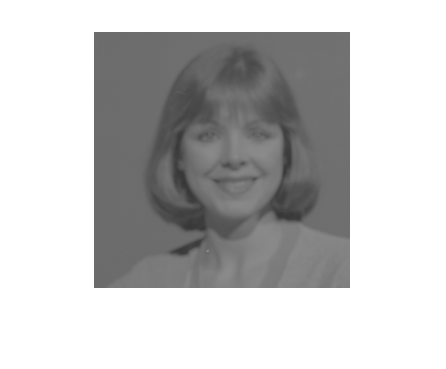

im = imread('wom1.png');
imshow(im);

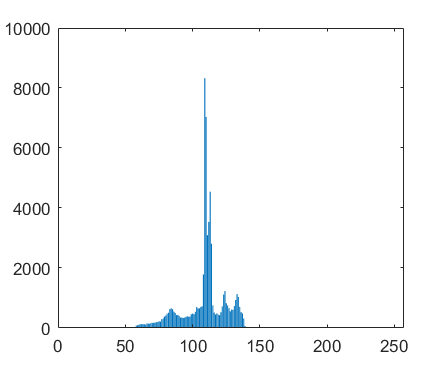


im_hist = sum((0:255) == im(:), 1);
bar(im_hist);

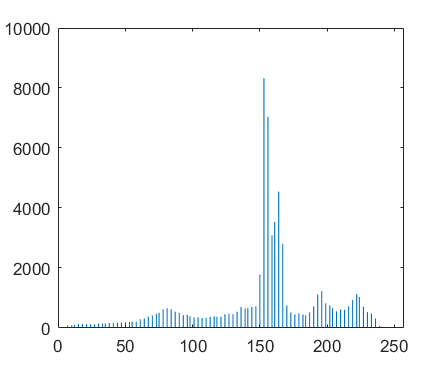

im_contrast_stretch = ContrastStretch(im);
im_contrast_stretch_hist = sum((0:255) == im_contrast_stretch(:), 1);
bar(im_contrast_stretch_hist);

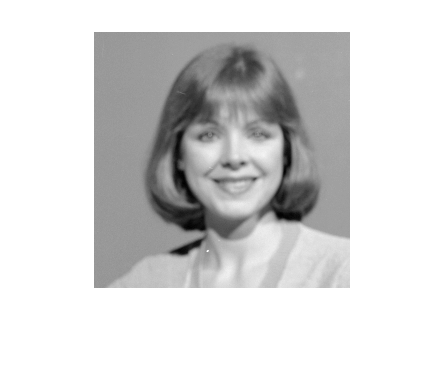


imshow(im_contrast_stretch);

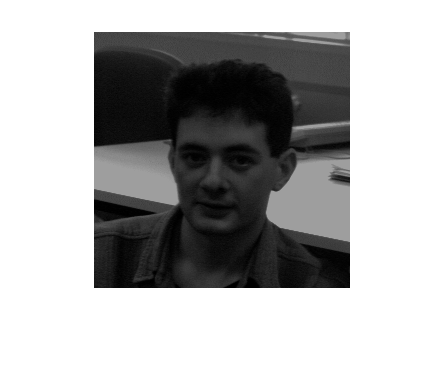

im_man8 = imread('man8.png');
imshow(im_man8);

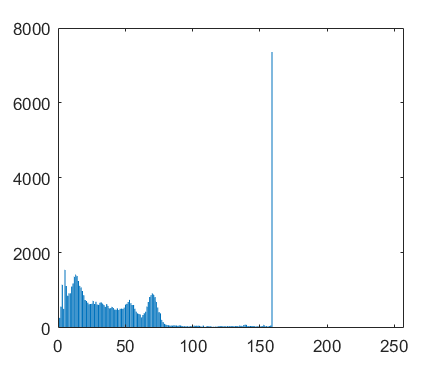

im_hist = sum((0:255) == im_man8(:), 1);
bar(im_hist);

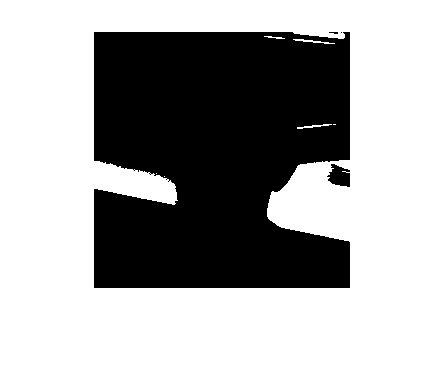


% From the histogram, we can see that there is a large fraction of pixels
% in the image have the same gray level.
m = max(im_man8(:));
im_bin = (im_man8 == m * ones(size(im_man8), 'uint8'));
imshow(im_bin);

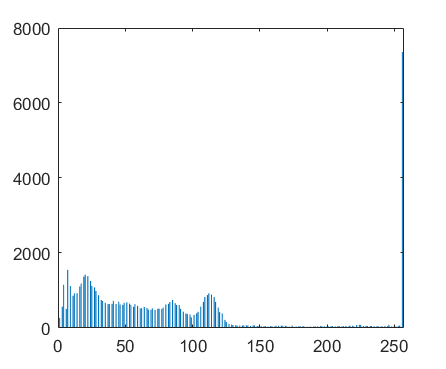


% ContrastStretch make the histogram become more spread but it does not
% affect the pixels that have highest and lowest gray level.
im_contrast_stretch = ContrastStretch(im_man8);
im_contrast_stretch_hist = sum((0:255) == im_contrast_stretch(:), 1);
bar(im_contrast_stretch_hist);

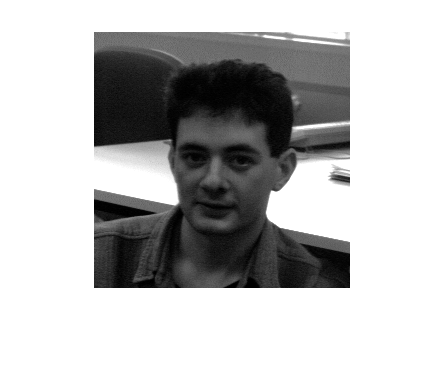


imshow(im_contrast_stretch);

## Task 2. Down sampling

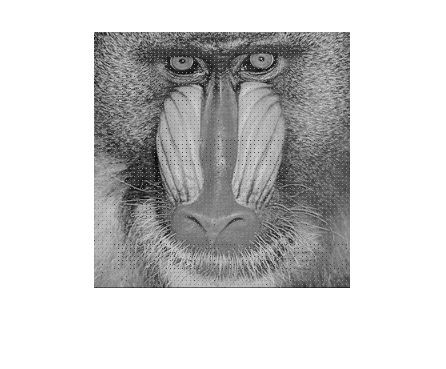

im = imread('mbaboon.bmp');
imshow(im);

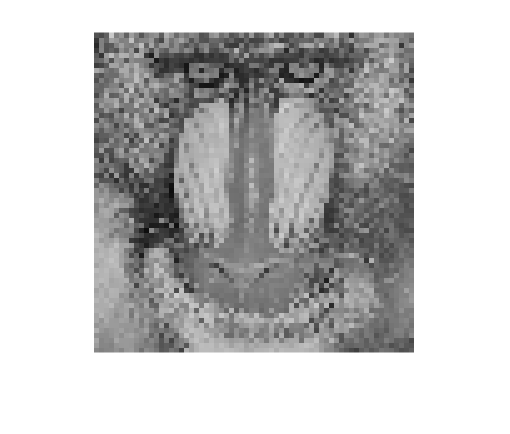


fun_replace_2x2 = @(block_struct) block_struct.data(2, 2);

im_replace_2x2 = blockproc(im, [4 4], fun_replace_2x2);
imshow(im_replace_2x2, 'InitialMagnification', 500);

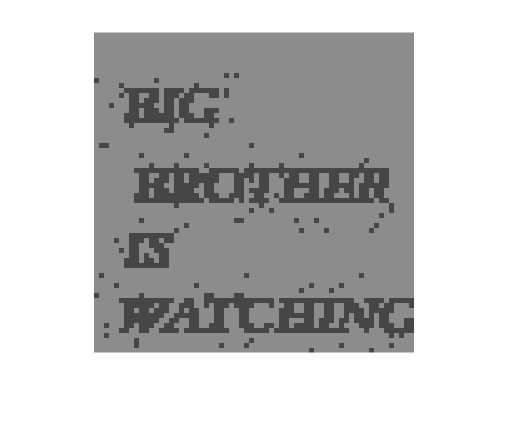

fun_replace_1x1 = @(block_struct) block_struct.data(1, 1);

im_replace_1x1 = blockproc(im, [4 4], fun_replace_1x1);
imshow(im_replace_1x1, 'InitialMagnification', 500);

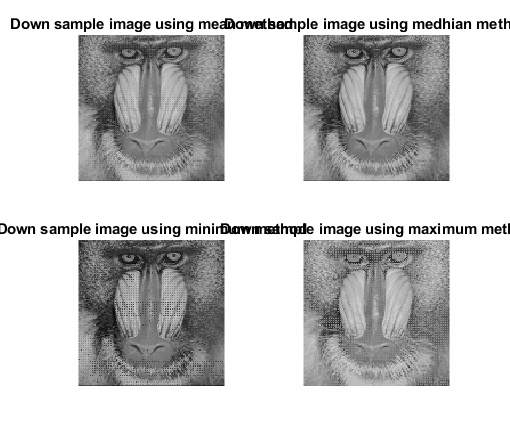

% Processing blocks using different methods.
fun_mean = @(block_struct) cast(mean(block_struct.data(:), 'all'), 'uint8');
fun_med = @(block_struct) cast(median(block_struct.data(:), 'all'), 'uint8');
fun_min = @(block_struct) min(block_struct.data(:), [], 'all');
fun_max = @(block_struct) max(block_struct.data(:), [], 'all');

subplot(2, 2, 1)
im_downsample_mean = blockproc(im, [2 2], fun_mean);
imshow(im_downsample_mean);
title('Down sample image using mean method');
set(gca, 'FontSize', 8);

subplot(2, 2, 2)
im_downsample_med = blockproc(im, [2 2], fun_med);
imshow(im_downsample_med);
title('Down sample image using medhian method');
set(gca, 'FontSize', 8);

subplot(2, 2, 3)
im_downsample_min = blockproc(im, [2 2], fun_min);
imshow(im_downsample_min);
title('Down sample image using minimum method');
set(gca, 'FontSize', 8);

subplot(2, 2, 4)
im_downsample_max = blockproc(im, [2 2], fun_max);
imshow(im_downsample_max);
title('Down sample image using maximum method');
set(gca, 'FontSize', 8);


% For subjective evaluation, I see the median method produce the
% most good-looking image.

## 3. Visual perception

If a person going on the street in a bright day, the eyes of that person adapt with the brightness of

of environment. When that person suddenly going to a dark theater, the brightness of surrounding

objects change quickly, so the eyes need time to adapt with this change, for example, increasing the

pupil size. The same phenomenon can happen, when we turn off lights in the house before go to bed.

## 4. Histogram

## (a)

The histogram corresponding to the gray level smller than min(255, 255 - c) and larger than max(0, -c) value will be shifted and remain the same shape.

For positive c, the number of pixels has maximum gray level may increase and the number of pixels has minimum gray level may decrease. Due to applying "max-cut off" and "min cut-off".

 For negative c, the number of pixels has maximum gray level may decrease and the number of pixels has maximum gray level may increase.

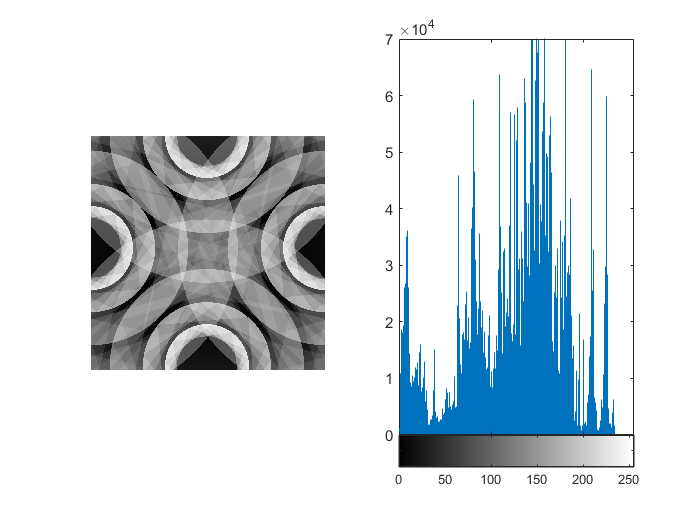

im = imread('O4HFU00.jpg');

figure;
subplot(1, 2, 1)
imshow(im);
subplot(1, 2, 2)
imhist(im);

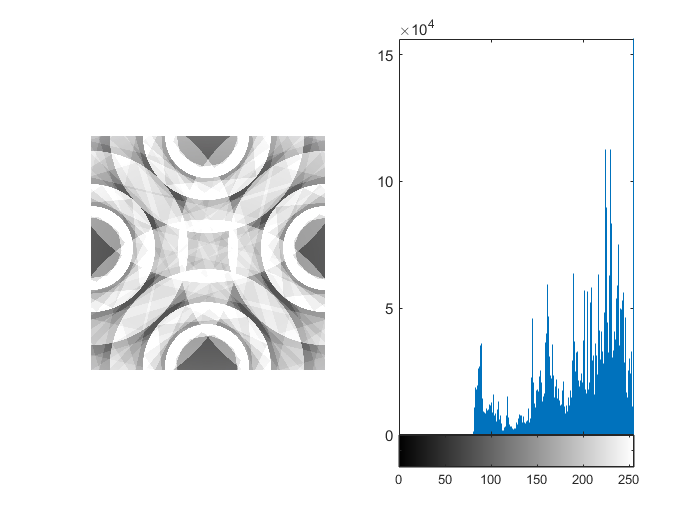


c_pos = 80;
im_shift_pos = double(im) + c_pos;
im_shift_pos = cast(min(im_shift_pos, 255), 'uint8');

figure;
subplot(1, 2, 1)
imshow(im_shift_pos);
subplot(1, 2, 2)
imhist(im_shift_pos);

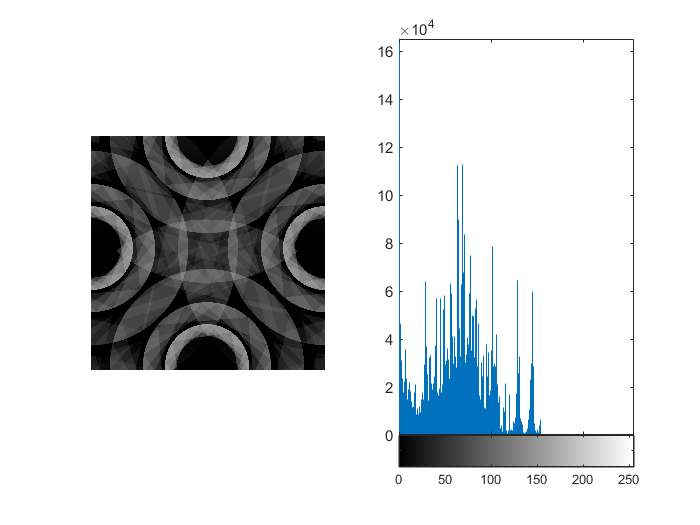


c_neg = -80;
im_shift_neg = double(im) + c_neg;
im_shift_neg = cast(max(im_shift_neg, 0), 'uint8');

figure;
subplot(1, 2, 1)
imshow(im_shift_neg);
subplot(1, 2, 2)
imhist(im_shift_neg);

## (b)

The histogram is stretching to the right for c > 1 and shrinking to the left for c < 1.

figure;
subplot(1, 2, 1)
imshow(im);
subplot(1, 2, 2)
imhist(im);

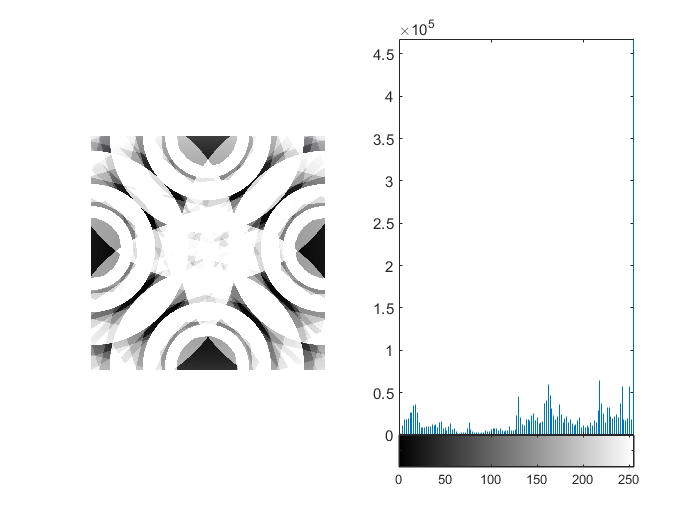


c_mul_stretch = 2;
im_stretch = c_mul_stretch * double(im);
im_stretch = cast(min(im_stretch, 255), 'uint8');

figure;
subplot(1, 2, 1)
imshow(im_stretch);
subplot(1, 2, 2)
imhist(im_stretch);

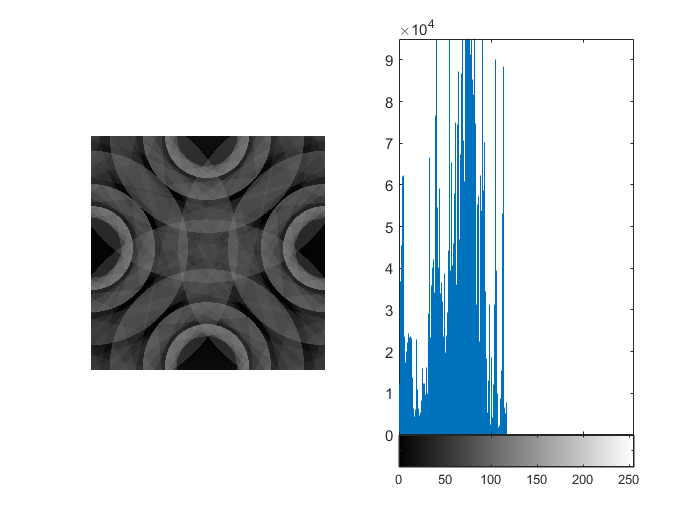


c_mul_shrink = 0.5;
im_shrink = c_mul_shrink * double(im);
im_shrink = cast(im_shrink, 'uint8');

figure;
subplot(1, 2, 1)
imshow(im_shrink);
subplot(1, 2, 2)
imhist(im_shrink);

## (c)

By rotating the image, the histogram will be the same.

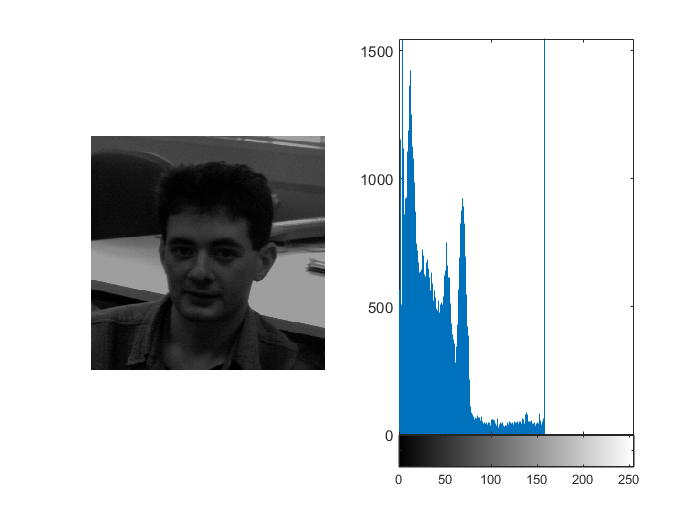

im = imread('man8.png');
im_rot90 = imrotate(im, 90);

figure;
subplot(1, 2, 1)
imshow(im);
subplot(1, 2, 2)
imhist(im);

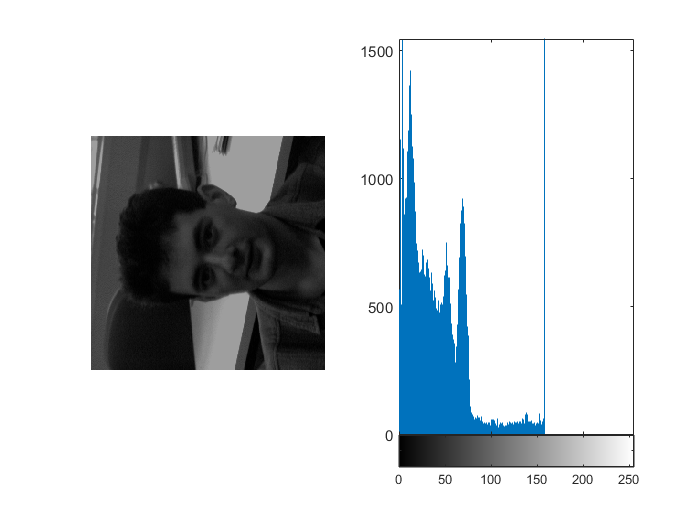


figure;
subplot(1, 2, 1)
imshow(im_rot90);
subplot(1, 2, 2)
imhist(im_rot90);